[hbar_v,hbar_un]=get_constant_value_units('hbar','eV')

hbar_v = 6.5821e-16

hbar_un = 'eV s'

[h_v,h_un]=get_constant_value_units('h','eV')

h_v = 4.1357e-15

h_un = 'eV s'

[c_v,c_un]=get_constant_value_units('c','eV')

c_v = 299792458

c_un = 'm s^-1'

[me_v,me_un]=get_constant_value_units('me','eV')

me_v = 5.4858e-04

me_un = 'eV/c^2'

lambda = 410e-9;

L_squre = (4*hbar_v^2*pi^2*lambda)/(me_v*h_v*c_v)

L_squre = 1.0310e-26

L = sqrt(L_squre)/1e-9

L = 1.0154e-04


Delta_E = h_v*c_v/lambda

Delta_E = 3.0240

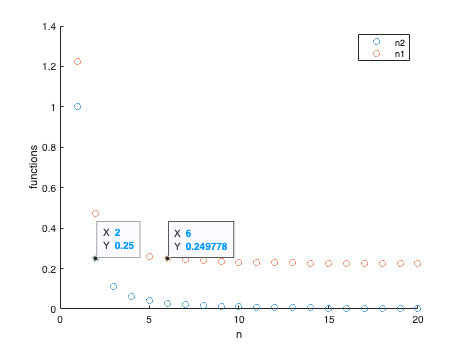



n1=1:1:20;
n2=1:1:20;

scatter(n2,1./(n2.^2))
hold on
scatter(n1,1./(n1.^2)+0.222)
legend({'n2','n1'})
xlabel('n')
ylabel('functions')

ax = gca;
chart = ax.Children(2);
datatip(chart,2,0.25);
chart = ax.Children(1);
datatip(chart,6,0.2498);
hold off

syms p(t) tau_p p_init p_final G_L x
ode = diff(p,t) == -p/tau_p

$$ode(t) = \frac{\partial }{\partial t}p\left(t\right)=-\frac{p\left(t\right)}{\tau_{p}}$$

pSol(t) = dsolve(ode)

$$pSol(t) = C_{1}\,{\mathrm{e}}^{-\frac{t}{\tau_{p}}}$$

cond1=p(0)==p_init;


conds = [cond1 cond2];
ode2 = diff(p,t)+(p/tau_p) == G_L

$$ode2(t) = \frac{p\left(t\right)}{\tau_{p}}+\frac{\partial }{\partial t}p\left(t\right)=G_{L}$$

p2Sol(t) = dsolve(ode2,cond)

$$p2Sol(t) = G_{L}\,\tau_{p}+{\mathrm{e}}^{-\frac{t}{\tau_{p}}}\,\left(p_{\mathrm{init}}-G_{L}\,\tau_{p}\right)$$

G_L = (heaviside(x)-heaviside(x-1)+heaviside(x-2 )-heaviside(x-3)+heaviside(x-4 )-heaviside(x-5)+heaviside(x-6 )-heaviside(x-7)...
    +heaviside(x-8 )-heaviside(x-9))

$$G\_L = \mathrm{heaviside}\left(x-2\right)-\mathrm{heaviside}\left(x-1\right)-\mathrm{heaviside}\left(x-3\right)+\mathrm{heaviside}\left(x-4\right)-\mathrm{heaviside}\left(x-5\right)+\mathrm{heaviside}\left(x-6\right)-\mathrm{heaviside}\left(x-7\right)+\mathrm{heaviside}\left(x-8\right)-\mathrm{heaviside}\left(x-9\right)+\mathrm{heaviside}\left(x\right)$$




D_p = G_L.*(1-exp(-x))

$$D\_p = \left({\mathrm{e}}^{-x}-1\right)\,\left(\mathrm{heaviside}\left(x-1\right)-\mathrm{heaviside}\left(x-2\right)+\mathrm{heaviside}\left(x-3\right)-\mathrm{heaviside}\left(x-4\right)+\mathrm{heaviside}\left(x-5\right)-\mathrm{heaviside}\left(x-6\right)+\mathrm{heaviside}\left(x-7\right)-\mathrm{heaviside}\left(x-8\right)+\mathrm{heaviside}\left(x-9\right)-\mathrm{heaviside}\left(x\right)\right)$$

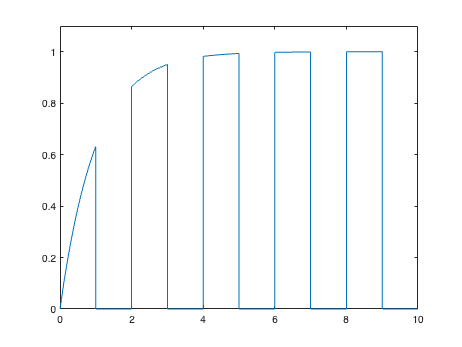

fplot(D_p,[0,10])
ylim([0,1.1])

disp('Not correct')

Not correct
